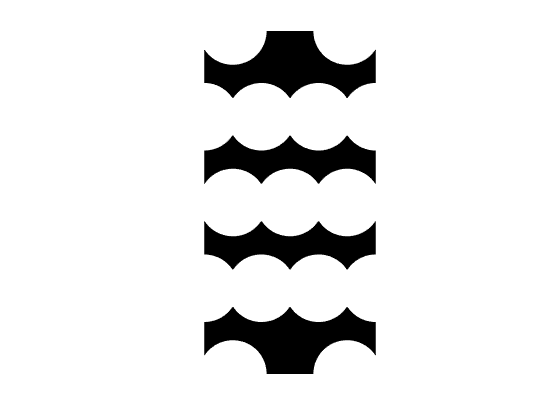

nelx=90;nely=180;volfrac=0.5;
%% LEVEL SET FUNCTION INITIALIZATION
r = nely*0.1;%RADIUS OF INITIAL HOLES
hX = nelx*[repmat([1/6,5/6],1,3),repmat([0,1/3,2/3,1],1,2),1/2];
hY = nely*[kron([0,1/2,1],ones(1,2)),kron([1/4,3/4],ones(1,4)),1/2];
[X,Y] = meshgrid(0:1:nelx,0:1:nely);
dX = bsxfun(@minus,repmat(X,[1,1,numel(hX)]),reshape(hX,1,1,numel(hX)));
dY = bsxfun(@minus,repmat(Y,[1,1,numel(hY)]),reshape(hY,1,1,numel(hY)));
Phi = max(-3,min(3,min(sqrt(dX.^2+dY.^2)-r,[],3)));
pGpX = ([Phi(:,2:end) zeros(nely+1,1)] - [zeros(nely+1,1) Phi(:,1:end-1)]);
pGpY = ([Phi(2:end,:);zeros(1,nelx+1)] - [zeros(1,nelx+1); Phi(1:end-1,:)]);
gradPhi = sqrt((pGpX).^2+(pGpY).^2);
figure(1); contourf(Phi,[0,0]);
colormap([0,0,0]); set(gcf,'color','w'); axis equal; axis off;

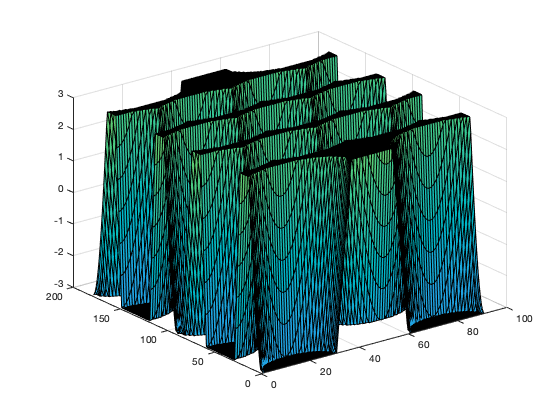

figure(2); surf(Phi); caxis([-12,12]);

No.1, Obj:1232742688490622208.000000, Vol:0.358957


No.2, Obj:281472979402394912.000000, Vol:0.387317


No.3, Obj:1602364566097.424316, Vol:0.759714


No.4, Obj:22599401716.638802, Vol:0.795212


No.5, Obj:26745435233831568.000000, Vol:0.625117


No.6, Obj:79620343049213056.000000, Vol:0.643285


No.7, Obj:63930179923128.203125, Vol:0.774971


No.8, Obj:624983017098406400.000000, Vol:0.260613


No.9, Obj:1145129508311096.500000, Vol:0.591441


No.10, Obj:1744532595359582976.000000, Vol:0.335438


No.11, Obj:34891004319.895111, Vol:0.635346


No.12, Obj:25515503265.352337, Vol:0.493686


No.13, Obj:21437866162.564449, Vol:0.529933


No.14, Obj:19021449094.095917, Vol:0.499674


No.15, Obj:17724366617.942177, Vol:0.508214


No.16, Obj:16887572838.309759, Vol:0.512894


No.17, Obj:16458293430.427927, Vol:0.515491


No.18, Obj:16156352547.144867, Vol:0.516761


No.19, Obj:15983416782.894272, Vol:0.516372


No.20, Obj:15831374072.249247, Vol:0.517310


No.21, Obj:15719561051.356628, Vol:0.518232


No.22, Obj:15624898273.324156, Vol:0.519257


No.23, Obj:15544851032.756741, Vol:0.520191


No.24, Obj:15473159301.678425, Vol:0.521169


No.25, Obj:15408964294.022985, Vol:0.522111


No.26, Obj:15352288793.036837, Vol:0.522910


No.27, Obj:15301013830.553143, Vol:0.523870


No.28, Obj:15250981515.385643, Vol:0.525078


No.29, Obj:15203581162.238253, Vol:0.526463


No.30, Obj:15156108735.592489, Vol:0.527999


No.31, Obj:15110719810.685902, Vol:0.529575


No.32, Obj:15067594354.248621, Vol:0.531090


No.33, Obj:15025525229.875141, Vol:0.532580


No.34, Obj:14985877877.331148, Vol:0.533994


No.35, Obj:14947577171.617853, Vol:0.535383


No.36, Obj:14910705497.217012, Vol:0.536714


No.37, Obj:14875086342.340509, Vol:0.538017


No.38, Obj:14841878010.875673, Vol:0.539232


No.39, Obj:14810076937.013132, Vol:0.540395


No.40, Obj:14779501102.368616, Vol:0.541508


No.41, Obj:14750878021.520128, Vol:0.542540


No.42, Obj:14723845711.973932, Vol:0.543503


No.43, Obj:14698445028.142771, Vol:0.544398


No.44, Obj:14674142131.425076, Vol:0.545236


No.45, Obj:14651473337.100430, Vol:0.545976


No.46, Obj:14630406390.948284, Vol:0.546620


No.47, Obj:14610585518.275673, Vol:0.547200


No.48, Obj:14592373529.312025, Vol:0.547693


No.49, Obj:14575376447.567902, Vol:0.548104


No.50, Obj:14559765362.417202, Vol:0.548428


No.51, Obj:14545785693.900034, Vol:0.548623


No.52, Obj:14533819587.741577, Vol:0.548650


No.53, Obj:14524129058.921797, Vol:0.548471


No.54, Obj:14517306001.140982, Vol:0.548097


No.55, Obj:14513263742.305477, Vol:0.547481


No.56, Obj:14513963069.094976, Vol:0.546379


No.57, Obj:14519020384.229437, Vol:0.545032


No.58, Obj:14526008730.282944, Vol:0.543466


No.59, Obj:14535178261.874949, Vol:0.541699


No.60, Obj:14542777508.541178, Vol:0.540340


No.61, Obj:14555255934.102812, Vol:0.538813


No.62, Obj:14564700405.735348, Vol:0.537107


No.63, Obj:14575330840.216476, Vol:0.535480


No.64, Obj:14589739416.555517, Vol:0.533590


No.65, Obj:14606857147.878159, Vol:0.531561


No.66, Obj:14625663876.882547, Vol:0.529497


No.67, Obj:14650817617.308254, Vol:0.527269


No.68, Obj:14674275664.770769, Vol:0.524995


No.69, Obj:14692739693.096987, Vol:0.522894


No.70, Obj:14713659647.750832, Vol:0.520777


No.71, Obj:14733968465.418312, Vol:0.518644


No.72, Obj:14756936143.579372, Vol:0.516493


No.73, Obj:14777626187.338606, Vol:0.514506


No.74, Obj:14798237079.567404, Vol:0.512514


No.75, Obj:14821987875.211395, Vol:0.510401


No.76, Obj:14845221060.290501, Vol:0.508247


No.77, Obj:14873081943.482290, Vol:0.505985


No.78, Obj:14899785139.607878, Vol:0.503853


No.79, Obj:14921381764.377764, Vol:0.501908


No.80, Obj:14948056269.137146, Vol:0.499780


No.81, Obj:14967142600.327068, Vol:0.497789


No.82, Obj:15000801155.571646, Vol:0.495321


No.83, Obj:15021919294.699303, Vol:0.493390


No.84, Obj:15044122499.101707, Vol:0.491396


No.85, Obj:15069479157.834019, Vol:0.489370


No.86, Obj:15087499922.297047, Vol:0.487440


No.87, Obj:15100127397.711962, Vol:0.485814


No.88, Obj:15115043177.812126, Vol:0.484502


No.89, Obj:15111492780.300253, Vol:0.483744


No.90, Obj:15112814010.498386, Vol:0.482975


No.91, Obj:15114314837.963848, Vol:0.482231


No.92, Obj:15114398855.780657, Vol:0.481672


No.93, Obj:15112530302.113659, Vol:0.481278


No.94, Obj:15109045378.022051, Vol:0.481025


No.95, Obj:15106243412.103146, Vol:0.480744


No.96, Obj:15100530667.070066, Vol:0.480676


No.97, Obj:15093906303.107937, Vol:0.480705


No.98, Obj:15085914358.337759, Vol:0.480838


No.99, Obj:15075979372.736008, Vol:0.481119


No.100, Obj:15066246310.700920, Vol:0.481415


No.101, Obj:15056136841.475697, Vol:0.481752


No.102, Obj:15045340923.866400, Vol:0.482158


No.103, Obj:15034187990.018415, Vol:0.482648


No.104, Obj:15021797713.056381, Vol:0.483265


No.105, Obj:15008885994.552814, Vol:0.483950


No.106, Obj:14994946094.365210, Vol:0.484726


No.107, Obj:14980279739.089933, Vol:0.485566


No.108, Obj:14965209535.835440, Vol:0.486473


No.109, Obj:14949570725.428740, Vol:0.487436


No.110, Obj:14933785098.028696, Vol:0.488445


No.111, Obj:14918020573.354101, Vol:0.489462


No.112, Obj:14901745569.010811, Vol:0.490550


No.113, Obj:14884897280.615177, Vol:0.491703


No.114, Obj:14868316159.099934, Vol:0.492850


No.115, Obj:14851877799.274014, Vol:0.494009


No.116, Obj:14835570492.687630, Vol:0.495189


No.117, Obj:14819421964.633894, Vol:0.496373


No.118, Obj:14803741704.224689, Vol:0.497536


No.119, Obj:14788721527.053020, Vol:0.498639


No.120, Obj:14774054731.570196, Vol:0.499717


No.121, Obj:14760156017.852333, Vol:0.500738


No.122, Obj:14746855983.347219, Vol:0.501704


No.123, Obj:14734142097.996754, Vol:0.502626


No.124, Obj:14721638696.660900, Vol:0.503517


No.125, Obj:14709374117.263678, Vol:0.504369


No.126, Obj:14697765969.686657, Vol:0.505168


No.127, Obj:14686969035.412678, Vol:0.505888


No.128, Obj:14677338263.382101, Vol:0.506519


No.129, Obj:14668425045.979568, Vol:0.507094


No.130, Obj:14660426203.523733, Vol:0.507586


No.131, Obj:14653322376.107430, Vol:0.507998


No.132, Obj:14647470258.220415, Vol:0.508315


No.133, Obj:14642749114.468554, Vol:0.508519


No.134, Obj:14638864029.878050, Vol:0.508632


No.135, Obj:14636117731.739782, Vol:0.508619


No.136, Obj:14634438534.692316, Vol:0.508520


No.137, Obj:14633879853.001192, Vol:0.508329


No.138, Obj:14634817183.907116, Vol:0.508024


No.139, Obj:14636858490.265593, Vol:0.507618


No.140, Obj:14639999576.230757, Vol:0.507127


No.141, Obj:14644518420.718262, Vol:0.506533


No.142, Obj:14650173243.621155, Vol:0.505839


No.143, Obj:14657010326.359905, Vol:0.505084


No.144, Obj:14665189547.187618, Vol:0.504277


No.145, Obj:14673782804.192556, Vol:0.503470


No.146, Obj:14680855713.184189, Vol:0.502664


No.147, Obj:14689005266.915880, Vol:0.501810


No.148, Obj:14697267623.044800, Vol:0.500977


No.149, Obj:14704900234.943615, Vol:0.500180


No.150, Obj:14711556672.528734, Vol:0.499438


No.151, Obj:14718177549.310072, Vol:0.498729


No.152, Obj:14724196109.339205, Vol:0.498074


No.153, Obj:14729711516.619955, Vol:0.497449


No.154, Obj:14734782105.949226, Vol:0.496884


No.155, Obj:14739484545.185734, Vol:0.496372


No.156, Obj:14743184328.281687, Vol:0.495941


No.157, Obj:14745964419.175856, Vol:0.495577


No.158, Obj:14747951213.043837, Vol:0.495284


No.159, Obj:14749275206.577044, Vol:0.495035


No.160, Obj:14749738493.669987, Vol:0.494863


No.161, Obj:14749335256.551977, Vol:0.494763


No.162, Obj:14748112415.641861, Vol:0.494734


No.163, Obj:14746381216.238733, Vol:0.494751


No.164, Obj:14744150896.018118, Vol:0.494811


No.165, Obj:14740945025.170206, Vol:0.494948


No.166, Obj:14737300743.672684, Vol:0.495124


No.167, Obj:14733249125.993088, Vol:0.495337


No.168, Obj:14728700962.904705, Vol:0.495589


No.169, Obj:14723933013.527567, Vol:0.495874


No.170, Obj:14718698586.720293, Vol:0.496197


No.171, Obj:14712993572.113611, Vol:0.496558


No.172, Obj:14707168537.977848, Vol:0.496935


No.173, Obj:14701090312.675686, Vol:0.497335


No.174, Obj:14695158192.532667, Vol:0.497728


No.175, Obj:14688917751.363640, Vol:0.498150


No.176, Obj:14682848566.479795, Vol:0.498561


No.177, Obj:14676933364.296938, Vol:0.498962


No.178, Obj:14671072102.872093, Vol:0.499365


No.179, Obj:14665500146.081408, Vol:0.499746


No.180, Obj:14659964836.560631, Vol:0.500108


No.181, Obj:14654506268.990252, Vol:0.500469


No.182, Obj:14649334744.371588, Vol:0.500809


No.183, Obj:14644388110.332197, Vol:0.501129


No.184, Obj:14639617089.367165, Vol:0.501435


No.185, Obj:14635253261.325130, Vol:0.501705


No.186, Obj:14631013376.365110, Vol:0.501963


No.187, Obj:14627163596.082962, Vol:0.502187


No.188, Obj:14623661414.666098, Vol:0.502381


No.189, Obj:14620453151.721041, Vol:0.502547


No.190, Obj:14617657332.146893, Vol:0.502683


No.191, Obj:14615281189.811052, Vol:0.502785


No.192, Obj:14613202218.832264, Vol:0.502856


No.193, Obj:14611566666.703173, Vol:0.502898


No.194, Obj:14610159255.143715, Vol:0.502918


No.195, Obj:14609215021.925076, Vol:0.502896


No.196, Obj:14608447671.347971, Vol:0.502856


No.197, Obj:14608202069.670835, Vol:0.502777


No.198, Obj:14608253647.989269, Vol:0.502670


No.199, Obj:14608591832.553398, Vol:0.502541


No.200, Obj:14609108888.134367, Vol:0.502389


No.201, Obj:14610036048.366043, Vol:0.502205


No.202, Obj:14611298123.624723, Vol:0.501988


No.203, Obj:14612747969.197142, Vol:0.501751


No.204, Obj:14614656896.970798, Vol:0.501468


No.205, Obj:14617069327.879148, Vol:0.501137


No.206, Obj:14619836388.635111, Vol:0.500773


No.207, Obj:14622927535.139231, Vol:0.500406


No.208, Obj:14625792047.128643, Vol:0.500065


No.209, Obj:14628376326.976812, Vol:0.499742


No.210, Obj:14630738069.892027, Vol:0.499437


No.211, Obj:14632880359.735003, Vol:0.499155


No.212, Obj:14635182930.026613, Vol:0.498856


No.213, Obj:14637176506.273960, Vol:0.498609


No.214, Obj:14638643126.939131, Vol:0.498399


No.215, Obj:14639629719.329580, Vol:0.498236


No.216, Obj:14640071222.747450, Vol:0.498111


No.217, Obj:14640083617.835619, Vol:0.498022


No.218, Obj:14639725946.992680, Vol:0.497966


No.219, Obj:14639174718.347797, Vol:0.497931


No.220, Obj:14638313490.468218, Vol:0.497918


No.221, Obj:14637148957.487892, Vol:0.497933


No.222, Obj:14635725121.528963, Vol:0.497965


No.223, Obj:14634278517.348440, Vol:0.498003


No.224, Obj:14632425151.651472, Vol:0.498076


No.225, Obj:14630500335.971176, Vol:0.498157


No.226, Obj:14628239386.917568, Vol:0.498258


No.227, Obj:14625901319.761621, Vol:0.498377


No.228, Obj:14623170932.669542, Vol:0.498532


No.229, Obj:14620366425.602436, Vol:0.498698


No.230, Obj:14617476098.433121, Vol:0.498871


No.231, Obj:14614504503.753908, Vol:0.499053


No.232, Obj:14611465042.600868, Vol:0.499243


No.233, Obj:14608560973.685856, Vol:0.499421


No.234, Obj:14605414386.236206, Vol:0.499617


No.235, Obj:14602383861.460520, Vol:0.499807


No.236, Obj:14599381798.788345, Vol:0.499993


No.237, Obj:14596428103.737217, Vol:0.500174


No.238, Obj:14593689463.585150, Vol:0.500340


No.239, Obj:14590868711.263889, Vol:0.500511


No.240, Obj:14588176868.184147, Vol:0.500670


No.241, Obj:14585570854.928532, Vol:0.500809


No.242, Obj:14583292736.798567, Vol:0.500938


No.243, Obj:14581035109.081179, Vol:0.501056


No.244, Obj:14579063570.097908, Vol:0.501150


No.245, Obj:14577325494.296040, Vol:0.501223


No.246, Obj:14575803835.150694, Vol:0.501280


No.247, Obj:14574306381.444180, Vol:0.501333


No.248, Obj:14573020750.522230, Vol:0.501370


No.249, Obj:14572004515.714205, Vol:0.501388


No.250, Obj:14571066256.546522, Vol:0.501397


No.251, Obj:14570328797.020212, Vol:0.501386


No.252, Obj:14569849109.813448, Vol:0.501354


No.253, Obj:14569457210.526247, Vol:0.501310


No.254, Obj:14569284802.921957, Vol:0.501248


No.255, Obj:14569123517.689413, Vol:0.501182


No.256, Obj:14569502891.458822, Vol:0.501062


No.257, Obj:14570003389.105137, Vol:0.500942


No.258, Obj:14570616876.385750, Vol:0.500812


No.259, Obj:14571430203.192793, Vol:0.500668


No.260, Obj:14572123781.750500, Vol:0.500538


No.261, Obj:14572907737.387526, Vol:0.500403


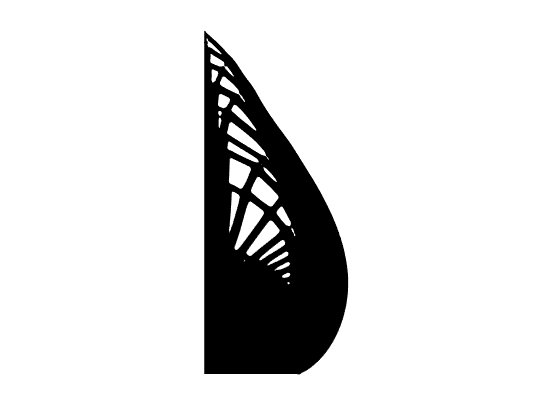

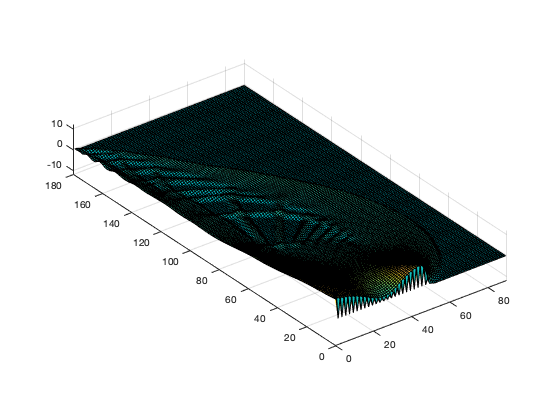

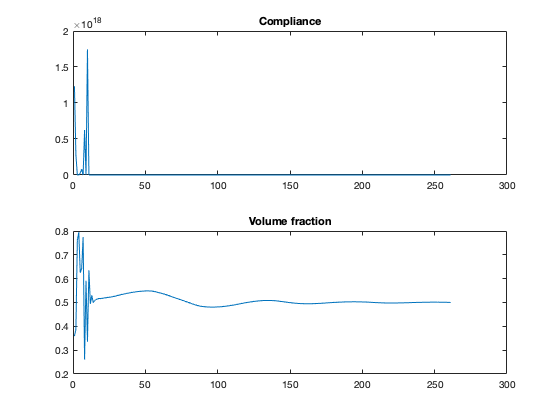

%% RADIAL BASIS FUNCTION INITIALIZATION
nNode = (nely+1)*(nelx+1);
Boundary = setdiff(unique([1:1:nely+1, nNode-nely:1:nNode, ...
    nely+1:nely+1:nNode, 1:nely+1:nNode-nely]), ...
    [[1:1:(nely+1)],[1:((nely+1)*2):(nNode-(nely+1)*2+1)]]);
Phi(Boundary)=-1e-9;
Alpha = Phi(:);
Phi = reshape(Alpha,nely+1,nelx+1);
%% FINITE ELEMENT ANALYSIS PREPARATION
E0 = 1; Emin = 1e-9; nu = 0.3; %MATERIAL PROPERTIES
A11 = [12 3 -6 -3; 3 12 3 0; -6 3 12 -3; -3 0 -3 12];
A12 = [-6 -3 0 3; -3 -6 -3 -6; 0 -3 -6 3; 3 -6 3 -6];
B11 = [-4 3 -2 9; 3 -4 -9 4; -2 -9 -4 -3; 9 4 -3 -4];
B12 = [ 2 -3 4 -9; -3 2 9 -2; 4 9 2 3; -9 -2 3 2];
KE = 1/(1-nu^2)/24*([A11 A12;A12' A11]+nu*[B11 B12;B12' B11]);
eleN1 = repmat((1:nely)',1,nelx)+kron(0:nelx-1,(nely+1)*ones(nely,1));
eleNode = repmat(eleN1(:),1,4)+repmat([0,nely+[1,2],1],nelx*nely,1);
edofMat = kron(eleNode,[2,2])+repmat([-1,0],nelx*nely,4);
iK = reshape(kron(edofMat,ones(8,1))',64*nelx*nely,1);
jK = reshape(kron(edofMat,ones(1,8))',64*nelx*nely,1);
%% BOUNDARY CONDITION DEFINITION
F = sparse([2*[1:1:(nely+1)]-1],ones(1,numel([1:1:(nely+1)])), ...
    [1:1:numel([1:1:(nely+1)])],2*nNode,1);
fixeddofs = [[1:((nely+1)*2):(nNode-(nely+1)*2+1)], ...
    [1:((nely+1)*2):(nNode-(nely+1)*2+1)]+1];
freedofs = setdiff(1:2*nNode,fixeddofs);
U = zeros(2*nNode,1);
%% ITERATION OPTIMIZATION
nLoop = 500; nRelax = 30;
dt = 0.02; delta = 10; mu = 20; gamma = 0.05;
comp = zeros(nLoop,1); vol = zeros(nLoop,1);
for iT = 1:nLoop
    %% FINITE ELEMENT ANALYSIS
        [s,t] = meshgrid(-1:0.1:1,-1:0.1:1);
    tmpPhi = (1-s(:)).*(1-t(:))/4*Phi(eleNode(:,1))'+(1+s(:)).*(1-t(:))/4*...
        Phi(eleNode(:,2))'+(1+s(:)).*(1+t(:))/4*Phi(eleNode(:,3))'+...
        (1-s(:)).*(1+t(:))/4*Phi(eleNode(:,4))';
    eleVol = sum(tmpPhi>=0,1)'/numel(s);
    vol(iT) = sum(eleVol)/(nelx*nely);
    sK = reshape(KE(:)*(Emin+eleVol'*(E0-Emin)),64*nelx*nely,1);
    K = sparse(iK,jK,sK); K = (K+K')/2;
    U(freedofs,1) = K(freedofs,freedofs)\F(freedofs,1);
    eleComp = sum((U(edofMat)*KE).*U(edofMat),2).*(Emin+eleVol*(E0-Emin));
    comp(iT) = sum(eleComp);
    %% DISPLAY RESULTS
    fprintf('No.%i, Obj:%f, Vol:%f\n',[iT,comp(iT),vol(iT)]);
    figure(3); contourf(Phi,[0,0]);
    colormap([0,0,0]); set(gcf,'color','w'); axis equal; axis off;
    %saveas(gcf,sprintf('Optim_pictures/%i.png', iT));
    figure(4); surf(Phi); caxis([-12,12]);
    axis equal; axis([0,nelx,0,nely,-12,12]); view(3);
    figure(5);  subplot(2,1,1); plot(comp(1:iT),'-'); title('Compliance');
                subplot(2,1,2); plot(vol(1:iT),'-'); title('Volume fraction');
    %% CONVERGENCE CHECK
    if iT>nRelax && abs(vol(iT)-volfrac)/volfrac<1e-3 && ...
        all(abs(comp(iT)-comp(iT-9:iT-1))/comp(iT)<1e-3)
        break;
    end
    %% LAGRANGE MULTIPLIER
    if iT<=nRelax
        lag = mu*(vol(iT)-vol(1)+(vol(1)-volfrac)*iT/nRelax);
    else
        lag = lag+gamma*(vol(iT)-volfrac);
        gamma = min(gamma+0.05,5);
    end
    %% LEVEL SET FUNCTION EVOLUTION
    pGpX = ([Phi(:,2:end) zeros(nely+1,1)] - [zeros(nely+1,1) Phi(:,1:end-1)]);
    pGpY = ([Phi(2:end,:);zeros(1,nelx+1)] - [zeros(1,nelx+1); Phi(1:end-1,:)]);
    gradPhi = sqrt((pGpX).^2+(pGpY).^2);
    indexDelta = (abs(Phi(:))<=delta);
    DeltaPhi = zeros(size(Phi));
    DeltaPhi(indexDelta) = 0.75/delta*(1-Phi(indexDelta).^2/delta^2);
    eleComp = reshape(eleComp,nely,nelx);
    eleCompLR = [eleComp(:,1),eleComp]+[eleComp,eleComp(:,end)];
    nodeComp = ([eleCompLR;eleCompLR(end,:)]+[eleCompLR(1,:);eleCompLR])/4;
    B = (nodeComp(:)/median(nodeComp(:))-lag).*DeltaPhi(:)*delta/0.75;
    Alpha = Alpha+dt*B;
    Alpha = Alpha/mean(gradPhi(unique(eleNode((eleVol<1 & eleVol>0),:))));%broke the program when the body is solid, but prevent oscilations
    Phi = reshape(Alpha,nely+1,nelx+1);
    Phi(Boundary)=min(Phi(Boundary),-1e-9);
end